# LAB 2 | Build-Your-Own Planet!

## Planetesimal Accretion Model

This exercise uses a simplified gravitational *n*-body model to simulate planetary accretion through planetesimal collisions and the compositional evolution of planetary embryos.

Planetesimals are initialised with random masses and positions within a disk extending to ~20 AU. A gas giant can optionally be placed at 5 AU from the central star.

The model tracks three components—metal, rock, and ice—assuming a radial distribution: metal- and rock-rich in the inner disk, ice-dominated beyond the snow line at 5 AU.

Collisions occur when bodies pass within an effective collision radius. The colliding masses, compositions, and momenta merge into a single body, positioned at the centre of mass and moving with momentum-conserving velocity.

## Task 1 – First Look

Begin by running the model with the default parameters set in the demo case. Click the **Run** button (green triangle) in the menu bar. To stop the simulation, click **Stop** (red square).

Output figures are saved in the `out/` folder of your MATLAB Drive or current working directory. Review the numbered frames to see how the accretion model evolves over time. What patterns do you notice?

Each time frame produces three figures:

- a **top view** of the protoplanetary disk,

- a **radial view** of the disk, and

- a **planetary zoo plot** of planetary radius vs. mass (relative to Earth).

In the disk views, body sizes are scaled to radius, with colours showing composition (red = metal core, green = rocky mantle, blue = icy envelope). The Sun and a gas giant appear in black (not to scale). For orientation, Earth’s orbit and size are indicated. The five most massive bodies are highlighted in magenta and shown at 3× magnification in the radial views.

## Task 2 – Parameter Testing

At the end of the script you will find several model parameters that can be adjusted within preset ranges. Explore these options and test a few variations. You only need to run each simulation briefly to see the effect of a new parameter set.

To save output figures separately for each test, assign a new run identifier each time. Use clear `Run IDs`, e.g. `NumberBodies500` for a run initialised with 500 bodies.

You can also change the `random seed`, which controls the initial random distribution of planetesimals. Adjusting this number produces unique outcomes for otherwise identical parameter sets.

## Task 3 –  Number and Mass of Planetesimals

Run three simulations with varying initial numbers and masses of planetesimals:

- 1000 bodies, average mass 0.01

- 300 bodies, average mass 0.03

- 2000 bodies, average mass 0.005

Set the stopping time to at least 100 years and increase the output interval to 300 or more to avoid excessive figures.

In each case, the total mass is similar, but distributed across different numbers of bodies. What differences do you observe in the simulation outcomes?

## Task 4 – Effects of a Gas Giant

The model includes a **gas giant **orbiting at 5 AU. Gas giants are thought to form early in protoplanetary disks, when icy particles and gas are abundant beyond the snow line. Their large mass strongly influences nearby orbits and the formation of later planets.

Run three simulations with gas giant masses of 10, 100, and 1000 Earth masses. Assign a new `Run ID` for each case, and run to at least 100 years with the output interval set to 300 or higher.

Which case corresponds roughly to Jupiter’s mass in our solar system? What differences do you observe as the gas giant becomes more massive?

## Task 5 – Final Simulation

The model artificially increases collision likelihood so that planets form within a manageable runtime. For this last test, increase the collision detection distance to 0.1 and run the model with as many bodies, and for as long, as time (and patience) allow.

At the final state, describe the five most massive bodies formed. Do they resemble any planets in our solar system? Comparing their mass and radius (relative to Earth’s radius shown on the plots) with the exoplanetary zoo figure, where would they fall? Terrestrial planet, super-Earth, water world, or ice giant?

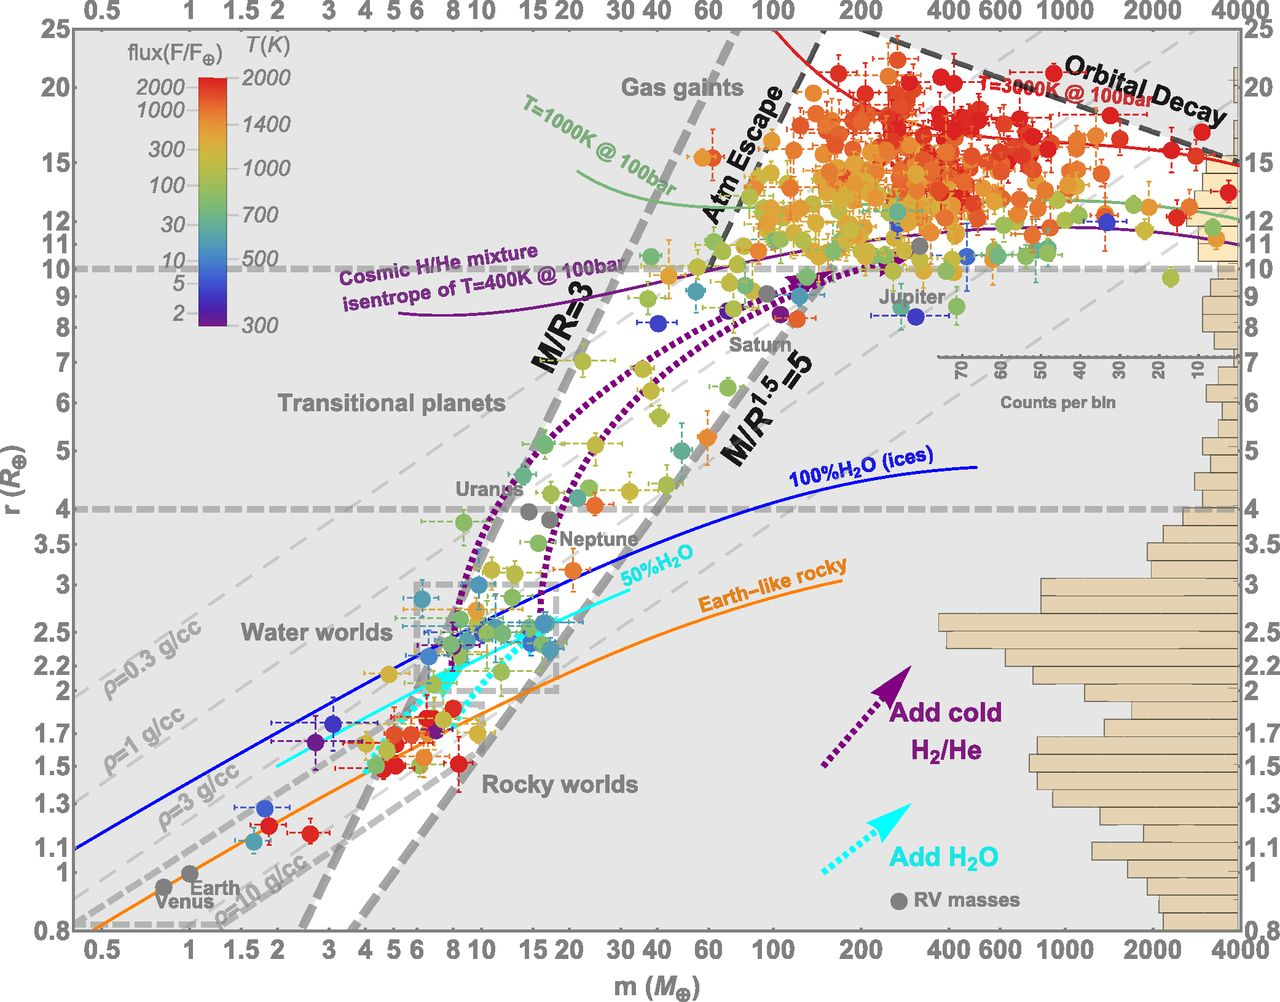

**Figure:** Exoplanetary Zoo after Zeng et al., *PNAS*, 2019 showing radius vs. mass of confirmed exoplanet discoveries. Data shown relative to Earth, with colour indicating estimated surface temperature and some trends indicating typical compositional categories. 

# Set Model Parameters

clear; close all; clc;  % clear workspace

Set run identifier tag. Output figures will be saved to folder `out/runID`. Set new identifier for every model run.

runID = 'byoplanet';  % change RunID for every parameter test

Set seed for random number generator. Adjust the slider to your favourite number to produce uniquely randomised results.

seed =15;  % change the random seed

Set interval of time steps between plotting and saving figures. Select lower interval for testing, higher for full model run.

nop  =  100;  % select lower interval for testing, higher interval for full run

Set model stopping time in years. Select shorter stopping time for testing, higher for full run. 

tend  =  100;  % select shorter stopping time for testing, higher for full run

Set initial condition for *n-*body simulation. Select the number of planetesimals, their mean mass, the mass of the gas giant planted at 5 AU, and the mass of the central star. All masses are given in Earth Masses.

N     = 1000;  % initial number of bodies
MPls  = 0.03;  % mean planetesimal mass [Earth Masses]
MGgt  = 300;  % mass of gas giant [Earth Masses]
MStr  = 3e5;  % mass of central star [Earth Masses]

Set effective collision radius: the radial distance [AU] to which nearby bodies are merged as collisions.

cls   = 0.03;  % collision radius [AU]

**Click on the button below or the Run button in the menu bar to start the model.**

 

restart = 0;
run('../src/main');